# Analyzing Re-Alignment

## Recollect all data


load('results_Matrix05.mat')
recollect_data

## calculation condition phases

theta_phases_condition = zeros([length(times), max(condition_positions), length(results)]);

freq_min = 5.5;
freq_max = 9;
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    for cond_ind = 1:size(theta_phases_condition,2)
        theta_phases_condition(:,cond_ind,subj_ind) = circ_mean(theta_phases_subject(:,results{subj_ind}.condition_positions == cond_ind),[],2);
    end
end

erp_phases_condition = [];
for subj_ind = 1:length(results)
    for cond_ind = 1:size(theta_phases_condition,2)
        erp_phases_condition(:,cond_ind,subj_ind) = get_hilbert_phase(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
    end
end


## Testing for different in phases

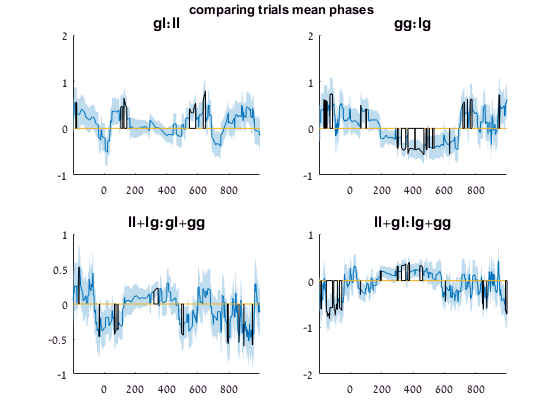

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(theta_phases_condition, 3, 1, u, t, p_thresh, n, false);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(theta_phases_condition, 4, 2, u, t, p_thresh, n, false);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(theta_phases_condition, 1:2, 3:4, u, t, p_thresh, n, false);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(theta_phases_condition, [1 3], [2 4], u, t, p_thresh, n, false);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases'

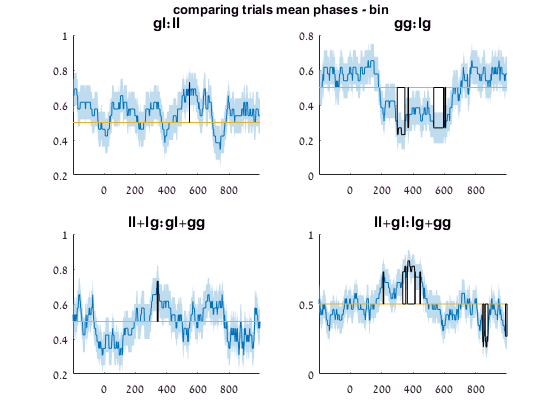

p_thresh = 0.01;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(theta_phases_condition, 3, 1, u, t, p_thresh, n, true)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(theta_phases_condition, 4, 2, u, t, p_thresh, n, true)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(theta_phases_condition, 1:2, 3:4, u, t, p_thresh, n, true)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(theta_phases_condition, [1,3], [2,4], u, t, p_thresh, n, true)
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases - bin'

## comparing to ERP

% p_thresh = 0.005;
% n = 1e3;
figure;
subplot(2,2,1)
show_perm_results(total_erps, 3, 1, u, t)

Cluster 1: time points 246 to 270, t-sum = 53.7986, p-value = 0.136186.
Cluster 2: time points 197 to 215, t-sum = 48.8085, p-value = 0.160884.
Cluster 3: time points 273 to 279, t-sum = 13.1411, p-value = 0.639036.
Cluster 4: time points 217 to 218, t-sum = 3.78999, p-value = 0.907809.
Cluster 5: time points 238 to 239, t-sum = 3.58423, p-value = 0.927607.
Cluster 6: time points 243 to 244, t-sum = 3.4641, p-value = 0.934707.
Cluster 7: time points 284 to 284, t-sum = 1.75644, p-value = 0.959504.


title 'gl:ll'
subplot(2,2,2)
show_perm_results(total_erps, 4, 2, u, t)

Cluster 1: time points 365 to 469, t-sum = 276.968, p-value = 0.00209979.
Cluster 2: time points 298 to 335, t-sum = 106.169, p-value = 0.039996.
Cluster 3: time points 344 to 346, t-sum = 5.50993, p-value = 0.859014.


title 'gg:lg '
subplot(2,2,3)
show_perm_results(total_erps, 1:2, 3:4, u, t)

Cluster 1: time points 507 to 554, t-sum = 121.161, p-value = 0.0168983.
Cluster 2: time points 98 to 105, t-sum = 22.9833, p-value = 0.464054.
Cluster 3: time points 562 to 568, t-sum = 15.2079, p-value = 0.627337.
Cluster 4: time points 500 to 503, t-sum = 7.63769, p-value = 0.833017.
Cluster 5: time points 571 to 573, t-sum = 7.52103, p-value = 0.837716.
Cluster 6: time points 575 to 577, t-sum = 6.15343, p-value = 0.867213.
Cluster 7: time points 182 to 183, t-sum = 3.65584, p-value = 0.950205.
Cluster 8: time points 33 to 33, t-sum = 2.20139, p-value = 0.961504.
Cluster 9: time points 5 to 5, t-sum = 1.82945, p-value = 0.971403.


title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_results(total_erps, [1,3], [2,4], u, t)

Cluster 1: time points 80 to 117, t-sum = 89.5408, p-value = 0.0440956.
Cluster 2: time points 39 to 47, t-sum = 21.3826, p-value = 0.486851.
Cluster 3: time points 31 to 33, t-sum = 6.8926, p-value = 0.841116.
Cluster 4: time points 594 to 595, t-sum = 3.56872, p-value = 0.946905.
Cluster 5: time points 70 to 71, t-sum = 3.54201, p-value = 0.948405.


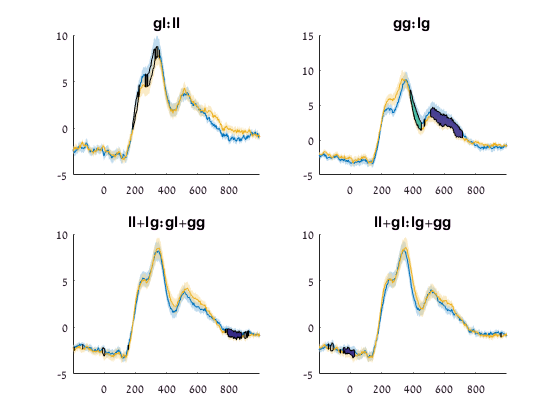

title 'll+gl:lg+gg'

ERP phases

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(erp_phases_condition, 3, 1, u, t, p_thresh, n, false)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(erp_phases_condition, 4, 2, u, t, p_thresh, n, false)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(erp_phases_condition, 1:2, 3:4, u, t, p_thresh, n, false)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(erp_phases_condition, [1,3], [2,4], u, t, p_thresh, n, false)
title 'll+gl:lg+gg'
title_subplots 'comparing ERP phases'


p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(erp_phases_condition(:,:,1:17), 3, 1, u, t, p_thresh, n, true)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(erp_phases_condition(:,:,1:17), 4, 2, u, t, p_thresh, n, true)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(erp_phases_condition(:,:,1:17), 1:2, 3:4, u, t, p_thresh, n, true)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(erp_phases_condition(:,:,1:17), [1,3], [2,4], u, t, p_thresh, n, true)
title 'll+gl:lg+gg'
title_subplots 'comparing ERP phases - bin'


## Testing phases using wavelets

phases_condition = zeros([length(freqs), length(times), max(condition_positions), length(results)]);
s_ = @squeeze;
for subj_ind = 1:length(results)
    phases_subject = s_(results{subj_ind}.phases);   
    for cond_ind = 1:size(phases_condition,3)
        phases_condition(:,:,cond_ind,subj_ind) = circ_mean(phases_subject(:,:,results{subj_ind}.condition_positions == cond_ind),[],3);
    end
end
% 
% erp_phases_condition = [];
% for subj_ind = 1:length(results)
%     for cond_ind = 1:size(theta_phases_condition,2)
%         erp_phases_condition(:,cond_ind,subj_ind) = get_hilbert_phase(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
%     end
% end


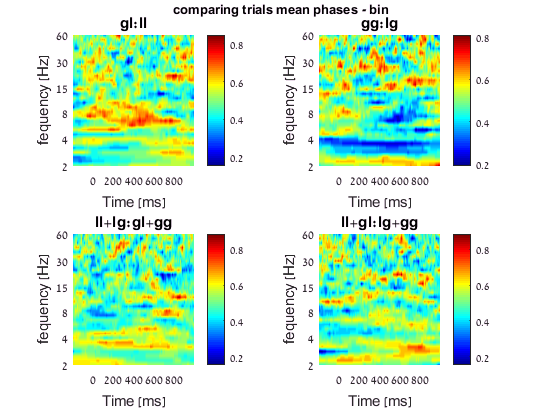

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(phases_condition, 3, 1, u, t, p_thresh, n, true, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(phases_condition, 4, 2, u, t, p_thresh, n, true, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(phases_condition, 1:2, 3:4, u, t, p_thresh, n, true, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(phases_condition, [1 3], [2 4], u, t, p_thresh, n, true, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases - bin'

## Just to compare: testing the powers

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(total_powers, 3, 1, u, t, p_thresh, n, false, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(total_powers, 4, 2, u, t, p_thresh, n, false, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(total_powers, 1:2, 3:4, u, t, p_thresh, n, false, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(total_powers, [1 3], [2 4], u, t, p_thresh, n, false, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean powers'


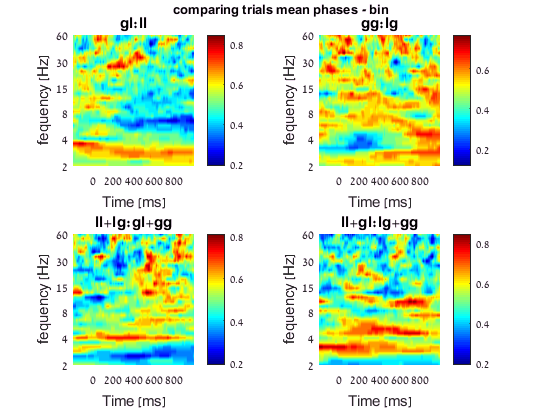

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(total_powers, 3, 1, u, t, p_thresh, n, true, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(total_powers, 4, 2, u, t, p_thresh, n, true, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(total_powers, 1:2, 3:4, u, t, p_thresh, n, true, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(total_powers, [1 3], [2 4], u, t, p_thresh, n, true, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean powers - bin'

function show_perm_phases(data, left_inds, right_inds, u, t, p_thresh, num_permutations, is_bin, freqs)

set_default('is_bin', false);
set_default('p_thresh', 0.05);
set_default('num_permutations', 1e4);

is2dData = ndims(data) == 4;

if left_inds<0
    left_inds = find(1:4 ~= -left_inds);
end
if right_inds<0
    right_inds = find(1:4 ~= -right_inds);
end

if is2dData
    trial_g_1 = squeeze(circ_mean(data(:,u,left_inds, :),[], 3));
    if right_inds ~= 0
        trial_g_2 = squeeze(circ_mean(data(:,u,right_inds, :),[], 3));
    end    
else
    trial_g_1 = squeeze(circ_mean(data(u,left_inds, :),[], 2));
    if right_inds ~= 0
        trial_g_2 = squeeze(circ_mean(data(u,right_inds, :),[], 2));
    end
end


if right_inds == 0
    trial_g_2 = [];
    trial_g = trial_g_1;
else
    trial_g = circ_dist(trial_g_1,trial_g_2);
end

if is_bin
    trial_g = 1*(trial_g>0);
    thresh_g = 0.5;
else 
    thresh_g = 0;
end

if is2dData
    permutest_2dplot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, true, t, freqs);
else
    permutest_plot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, t, false);
end

end


function test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, t0, freq_min, freq_max, align_by_erp)


set_default('align_by_erp', false)

t_zero = t0;
N_subjects = length(results);
t=times(u);
total_powers_aligned = zeros([length(freqs), length(times), N_subjects]);

sub_powers_aligned = total_powers_aligned;
total_erps_aligned = zeros([ length(times)  N_subjects]);


for sub_ind = 1:N_subjects
    result = results{sub_ind};
    trials = result.trials;
    power_raw = result.power_raw;
    
    if align_by_erp
        phase_shifts = get_hilbert_phase_shift(mean(trials,3), freq_min, freq_max, SamplingInterval);
        phase_shifts = repmat(phase_shifts,1,size(trials,3));
    else
        phase_shifts = get_hilbert_phase_shift(trials, freq_min, freq_max, SamplingInterval);
    end
    shift = phase_shifts(find(times>t_zero,1),:);
    aligned_trials = align_trials_by_shift(trials, shift);
    aligned_erp = mean(aligned_trials(:,1,:),3);
    aligned_power = align_power_by_shift(power_raw, shift);
    aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);
    
    sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
    sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
    sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);
    
    total_powers_aligned(:,:,sub_ind) = squeeze(aligned_power);
    sub_powers_aligned  (:,:,sub_ind) = squeeze(sub_aligned_power);
    total_erps_aligned(:,sub_ind) = aligned_erp;
    
end

title_freq = sprintf('@ t=%d ms, f=%.1f-%.1f Hz', t_zero, freq_min, freq_max);
if align_by_erp
    title_freq = ['shift by subjects'' ERP' title_freq];
end

figure;
show_powers_tight(t, freqs, cat(3, ...
    squeeze(mean(total_powers(:,u,:),3)), ...
    squeeze(mean(sub_powers(:,u,:),3)), ...
    squeeze(mean(total_powers(:,u,:),3))-squeeze(mean(sub_powers(:,u,:),3)), ...
    mean(total_powers_aligned(:,u,:),3), ...
    mean(sub_powers_aligned(:,u,:),3), ...
    mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3)),...
    3, title_freq, 'Power [db]', [], ...
    {'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'})

figure;
subplot(1,2,1);
varplot(times, squeeze(mean(total_erps,2)))

title({'original trials'})
subplot(1,2,2);
varplot(times, total_erps_aligned)
title({'aligned trials ' title_freq})

end

function norm_power = norm_power_bl_range(power, bl_range)
bl_values = mean(mean(power(:, bl_range, :),3),2);
norm_power = 10 * log10(bsxfun(@rdivide,mean(power,3),bl_values));
end

